%The data  for each of the input and outputs was exported from LTSpice into .txt files - op1.txt,op2.txt,inp1.txt,inp2.txt and is used here

%I**mport data into matlab variables (struct and from it arrays)**

output1=importdata('op1_wogb.txt')

output1 = struct with fields:
          data: [329024×2 double]
      textdata: {'time'  'V(demodulated_signal1)'}
    colheaders: {'time'  'V(demodulated_signal1)'}


op1=output1.data(:,2);                    %Extracting the datafrom struct output1 which corresponds to the demodulator output op1
t_op1=output1.data(:,1);                  %Extracting discrete time instants
T1=t_op1(80000)-t_op1(30000);             %Extracting the sampling frequency used
fs1=50000/T1;


**%Plot the SNR**

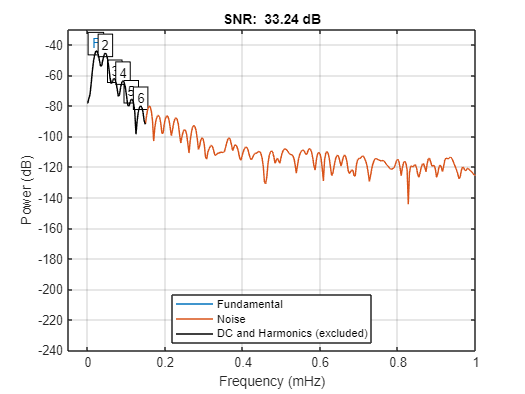

figure(1);                                %Plotting the Signal To Noise ratio PSD plot
snr(op1);
xlim([-0.05,1]);

**%Repeat Above steps for second input and output**

output2=importdata('op2_wogb.txt')

output2 = struct with fields:
          data: [329024×2 double]
      textdata: {'time'  'V(demodulated_signal2)'}
    colheaders: {'time'  'V(demodulated_signal2)'}


op2=output2.data(:,2);                    %Extracting the datafrom struct output1 which corresponds to the demodulator output op1
t_op2=output2.data(:,1);                  %Extracting discrete time instants
T2=t_op2(80000)-t_op2(30000);             %Extracting the sampling frequency used
fs2=50000/T1;


**%Plot the SNR**

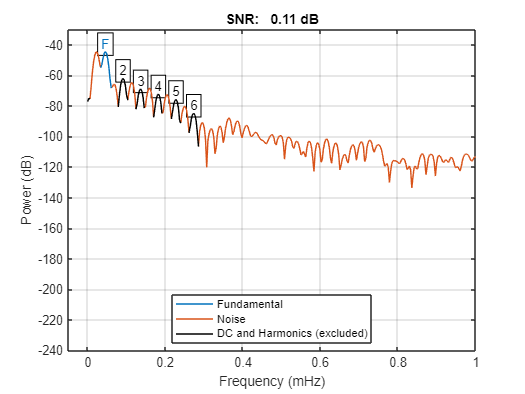

figure(2);                                %Plotting the Signal To Noise ratio PSD plot
snr(op2);
xlim([-0.05,1]);